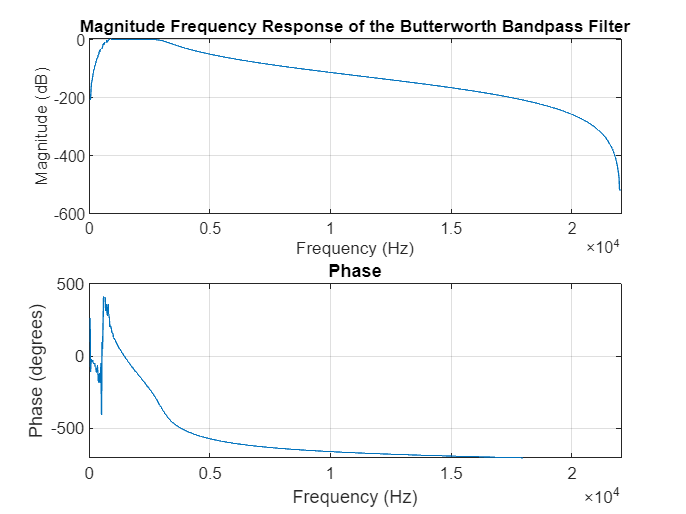

% Load audio data from file1
file1 = 'Train\S_1.wav';
[data1, fs1] = audioread(file1);
%sound(data1, fs1);

% Apply Butterworth bandpass filter to file1
low_cutoff_frequency = 700; % Adjust the low cutoff frequency as needed
high_cutoff_frequency = 3000; % Adjust the high cutoff frequency as needed
order = 8; % Adjust the filter order as needed
[b, a] = butter(order, [low_cutoff_frequency, high_cutoff_frequency] / (fs1/2), 'bandpass');

% Plot the frequency response of the Butterworth filter
figure;
freqz(b, a, 1024, fs1)
title('Magnitude Frequency Response of the Butterworth Bandpass Filter');

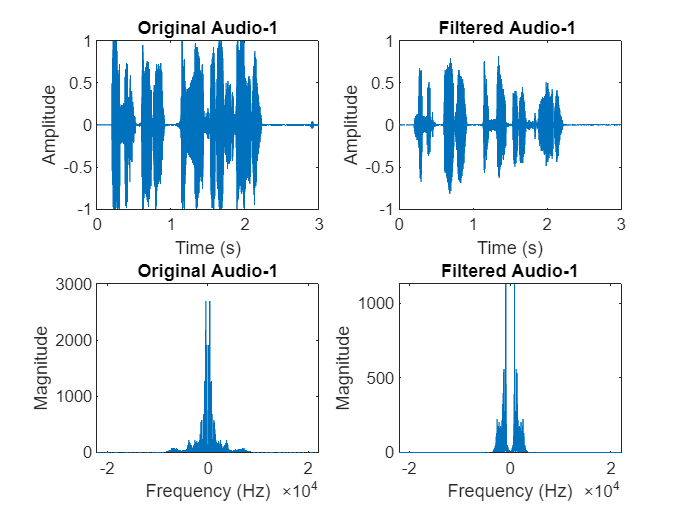



filtered_data1 = filtfilt(b, a, data1);
%sound(filtered_data1, fs1);

figure;
subplot(2,2,1);
t = (0:length(data1 )-1) / fs1;
plot(t,data1 );
title('Original Audio-1');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(filtered_data1 )-1) / fs1; % Time vector

subplot(2,2,2);
plot(t, filtered_data1 );
title('Filtered Audio-1 ');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(data1 ) ; % Set n based on the length of the signal
y = fft(data1 , n);
m = abs(y);
f = (0:length(y)-1) * fs1 / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (fs1/n);

% Filtered
nf = length(filtered_data1 );  % Set n based on the length of the signal
yf = fft(filtered_data1 , nf);
mf = abs(yf);
ff = (0:length(yf)-1) *fs1 / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (fs1/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original Audio-1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered Audio-1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

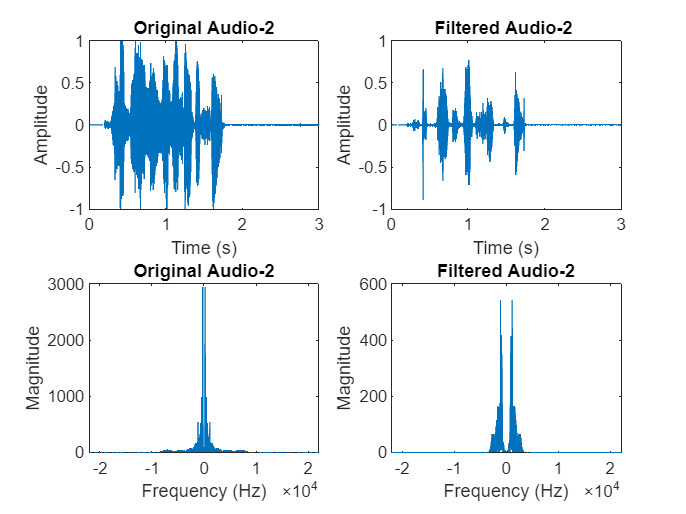


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Load audio data from file2
file2 = 'Train\A_2.wav';
[data2, fs2] = audioread(file2);
%sound(data2, fs1);
% Apply Butterworth bandpass filter to file2
filtered_data2 = filtfilt(b, a, data2);
%sound(filtered_data2, fs1);

figure;
subplot(2,2,1);
t = (0:length(data2 )-1) / fs1;
plot(t,data2 );
title('Original Audio-2');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(filtered_data2 )-1) / fs2; % Time vector

subplot(2,2,2);
plot(t, filtered_data2 );
title('Filtered Audio-2 ');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(data2 );  % Set n based on the length of the signal
y = fft(data2 , n);
m = abs(y);
f = (0:length(y)-1) * fs1 / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (fs1/n);

% Filtered
nf = length(filtered_data2 );  % Set n based on the length of the signal
yf = fft(filtered_data2 , nf);
mf = abs(yf);
ff = (0:length(yf)-1) *fs1 / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (fs1/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original Audio-2');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered Audio-2');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

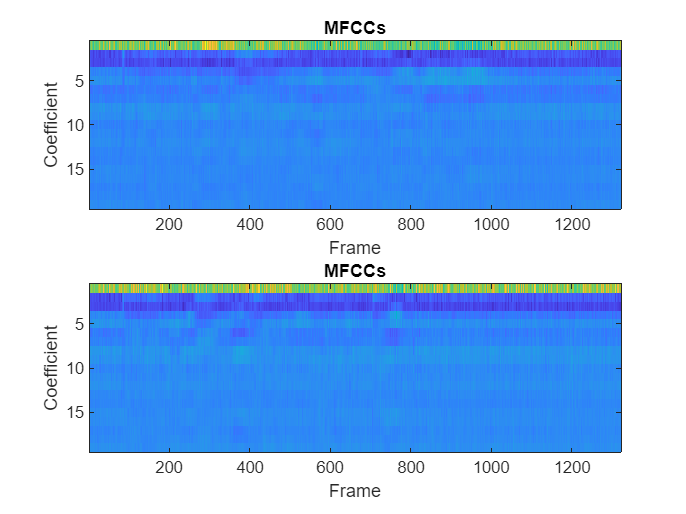


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Calculate MFCC Coefficients for filtered_data1
melCeps1 = getMFCC(filtered_data1, fs1);

% Plotting MFCCs
figure;
subplot(2,1,1);
imagesc(melCeps1);
title('MFCCs');
xlabel('Frame');
ylabel('Coefficient');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Calculate MFCC Coefficients for filtered_data2
melCeps2 = getMFCC(filtered_data2, fs1);

% Plotting MFCCs
subplot(2,1,2);
imagesc(melCeps2)
title('MFCCs');
xlabel('Frame');
ylabel('Coefficient');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Use DTW to compare the two sets of MFCCs
dist = dtw(melCeps1', melCeps2');

% Print distance between the two audio files
if dist < 1150
    fprintf('Distance between audio files: %f\n', dist);
    fprintf('Login successful.\n');
else
    fprintf('Distance between audio files: %f\n', dist);
    fprintf('Login failed.\n');
end

Distance between audio files: 1202.534035


Login failed.


function melCeps = getMFCC(data, fs)

% Computing MFCC Co-efficients
N = 256;   % N point FFT
M = 100;   % Overlapping

% Frame Blocking
NN = floor(N/2+1); %N/2
nbFrames = ceil((length(data)-N)/M);
Frames = zeros(nbFrames+1, N);
for i = 0:nbFrames-1
    temp = data(i*M+1:i*M+N);
    Frames(i+1, 1:N) = temp;
end

% Last Frame
temp = zeros(1, N);
lastLength = length(data)-nbFrames*M;
temp(1:lastLength) = data(nbFrames*M+1:(nbFrames*M+1+lastLength-1));
Frames(nbFrames+1, 1:N) = temp;

% Windowing
frameSize = size(Frames);
nbFrames = frameSize(1);
nbSamples = frameSize(2);

% Hamming window
w = hamming(nbSamples);
Windows = zeros(nbFrames, nbSamples);
for i = 1:nbFrames
    temp = Frames(i, 1:nbSamples);
    Windows(i, 1:nbSamples) = w'.*temp;
end

% Fourier Transform
ffts = fft(Windows');

% Mel-frequency Wrapping
% Calculate Power spectrum
PowSpecs = abs(ffts).^2;
PowSpecs = PowSpecs(1:NN-1, :);

% Mel filter generation
nof_c = 20; % Number of channels
df = fs/N;
Nmax = N/2;
fmax = fs/2;

% Convert to mel scale
melmax = 2595*log10(1+fmax/700);
melinc = melmax/(nof_c+1);
melcenters = (1:nof_c).*melinc;

% Convert to frequency scale
fcenters = 700*((10.^(melcenters./2595))-1);
centerf = round(fcenters./df);
startf = [1, centerf(1:nof_c-1)];
stopf = [centerf(2:nof_c), Nmax];

W = zeros(nof_c, Nmax);

% Making filter
for i = 1:nof_c
    increment = 1.0/(centerf(i)-startf(i));
    for j = startf(i):centerf(i)
        W(i, j) = (j-startf(i))*increment;
    end

    decrement = 1.0/(stopf(i)-centerf(i));
    for j = centerf(i):stopf(i)
        W(i, j) = (j-centerf(i))*decrement;
    end
end

% Normalising
for i = 1:nof_c
    W(i, :) = W(i, :)/sum(W(i, :));
end

% Apply mel filters to Power spectrum coeffs
melPowSpecs = W*PowSpecs;

% MFCC calculations
melCeps = dct(log(melPowSpecs));
melCeps(1, :) = [];

end



